# Natick Elevation

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

data = readtable("./data/natick.txt")

data = 234×3 table
    latitude    longitude    elevation
    ________    _________    _________

     71.208      42.405        2079   
     71.225      42.405        2007   
     71.242      42.405        2169   
     71.258      42.405        2373   
     71.275      42.405        2279   
     71.292      42.405        2375   
     71.308      42.405        2213   
     71.325      42.405        2065   
     71.342      42.405        1933   
     71.358      42.405        2081   
     71.375      42.405        2269   
     71.392      42.405        2191   
     71.408      42.405        2065   
     71.208      42.392        2223   
     71.225      42.392        2131   
     71.242      42.392        2353   


xv = min(data.latitude):0.01:max(data.latitude);
yv = min(data.longitude):0.01:max(data.longitude);
[X, Y] = meshgrid(xv, yv);
Z = griddata(data.latitude, data.longitude, data.elevation, X, Y);

## Task 1

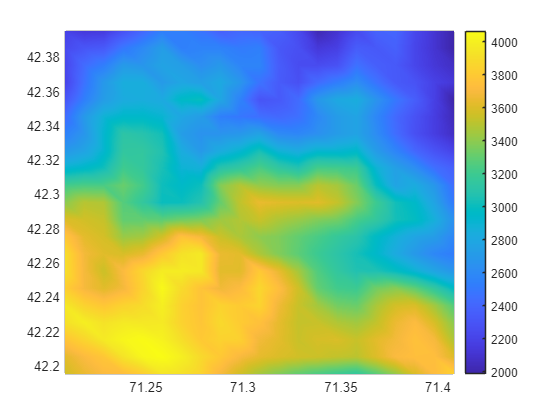

s = pcolor(X, Y, Z);
s.EdgeColor = "none";
s.FaceColor = "interp";
colorbar